# EL2520 Computer Exercise 1

## 4.1 | Basics

s = tf('s');
G = 3*(-s+1)/((5*s+1)*(10*s+1));

% bode(G) % Display bode plot
% title('Bode Diagram | G')
%[Gm,Pm,wp,wc] = margin(G); % Phase margin, amplitude margin, and corresp. freqs. of G

% Contruct lead-lag controller

% Design criteria
w_cd = 0.4; % omega_c,d [rad/s]
p_m = 30; % phi_m [deg]

% Determine 'phase lift' needed form controller
lag_comp = 6; % rule of thumb is to use 6 [deg]
[m,p] = bode(G, w_cd); % Amplitude and phase of system at w_cd

p_lift = -180 + p_m - p + lag_comp;
p_lift  = p_lift +  360; % Move into range on graph 

% Set manually
b = .55; % beta - from graph based on p_lift
g = 0.01; % gamma - very small or zero

% Calculate
t_d = 1/(w_cd*sqrt(b)); % tau_d
t_I = 10/w_cd; % tau_I

lead = (t_d*s+1)/(b*t_d*s+1); % Without K
lag = (t_I*s+1)/(t_I*s+g);

[m2,p2] = bode(G*lead, w_cd); % Amplitude and phase at w_cd
K = 1/m2; % = sqrt(b)/m

lead = K*lead;
F = lead*lag;

fprintf('beta = %f', b)
fprintf('tau_d = %f', t_d)
fprintf('tau_I = %d', t_I)
fprintf('K = %f', K)

bode(G*F)
title('Bode Diagram | G * F')
grid on
step(G*F)
title('Step | G * F')
grid on


## 4.2 | Disturbance Attenuation

### 4.2.1


s = tf('s');
G = 20/((s+1)*((s/20)^2+(s/20)+1));
G_d = 10/(s+1);
%bode(G_d)

% Design F_y such that L(s) ~ w_c/s
[Gm,Pm,wp,wc] = margin(G_d); % Phase margin, amplitude margin, and corresp. freqs. of G_d
w_design = 10*wc; % Design

F_y  = G\w_design/s; % = inv(G)*w_design/s

% Add poles
poles = [-1000, -1000, -1000];
F_y = add_poles(F_y, poles)

% Calc transfer func from 'd' to 'y'
G_dy = G_d / (1 + F_y*G);

bode(G_dy)
grid on
step(G_dy)
grid on


### 4.2.2

s = tf('s');
G = 20/((s+1)*((s/20)^2+(s/20)+1));
G_d = 10/(s+1);

[Gm,Pm,wp,wc] = margin(G_d); % Phase margin, amplitude margin, and corresp. freqs. of G_d
w_I = wc; % Design

F_y  = ((s+w_I)/s)*inv(G)*G_d;



ans =
 
  0.00125 s^3 + 0.03743 s^2 + 0.7487 s + 4.974
  --------------------------------------------
                       s
 
Continuous-time transfer function.



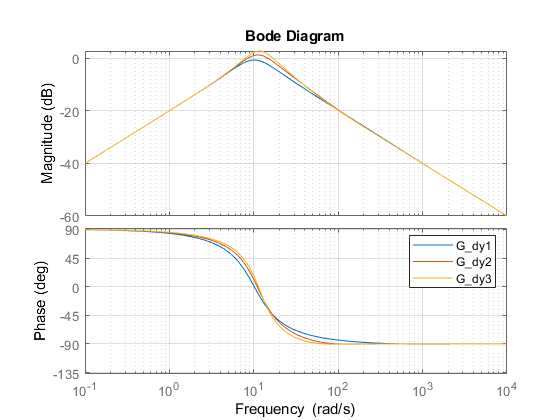

% Test different added pole configurations
% Add poles
poles1 = [-1000, -1000, -1000];
F_y1 = add_poles(F_y, poles1);
poles2 = [-100, -100, -1000];
F_y2 = add_poles(F_y, poles2);
poles3 = [-50, -100, -1000];
F_y3 = add_poles(F_y, poles3);

% Calc transfer func from 'd' to 'y'
G_dy1 = G_d / (1 + F_y1*G);
G_dy2 = G_d / (1 + F_y2*G);
G_dy3 = G_d / (1 + F_y3*G);

bode(G_dy1, G_dy2, G_dy3)
legend
grid on

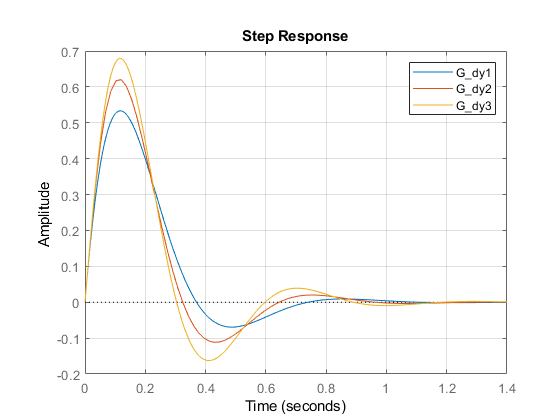

step(G_dy1, G_dy2, G_dy3)
legend
grid on

### 4.2.3

s = tf('s');
G = 20/((s+1)*((s/20)^2+(s/20)+1));
G_d = 10/(s+1);

[Gm,Pm,wp,wc] = margin(G_d); % Phase margin, amplitude margin, and corresp. freqs. of G_d
w_I = 2*wc; % Design

F_y  = ((s+w_I)/s)*inv(G)*G_d;

% Add poles
poles = [-1000, -1000, -1000];
F_y = add_poles(F_y, poles);

% Calc transfer func from 'r' to 'y'
F_r = 1; % Init F_r to 1 for now
G_c = G*F_y*F_r / (1 + G*F_y);

% bode(G_c)
% legend
% grid on
% step(G_c)
% legend
% grid on

% Add zeros to reduce overshoot
zeros = [-5];
F_y_zeroed = add_zeros(F_y, zeros);

% Calc transfer func from 'r' to 'y'
G_c_zeroed = G*F_y_zeroed*F_r / (1 + G*F_y_zeroed);
% G_c_zeroed = minreal(G_c_zeroed);

% Add F_r to prefilter reference
tau = 0.08;
F_r = 1/(1+ tau*s);

% Calc transfer func from 'r' to 'y'
G_c_prefilt = G*F_y_zeroed*F_r / (1 + G*F_y_zeroed);

minreal(F_y_zeroed)


ans =
 
  250000 s^4 + 1.122e07 s^3 + 2.493e08 s^2 + 2.987e09 s + 9.947e09
  ----------------------------------------------------------------
                 s^4 + 3000 s^3 + 3e06 s^2 + 1e09 s
 
Continuous-time transfer function.



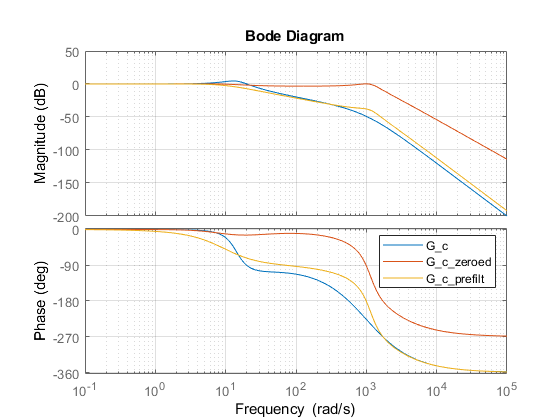


bode(G_c, G_c_zeroed, G_c_prefilt)
legend
grid on

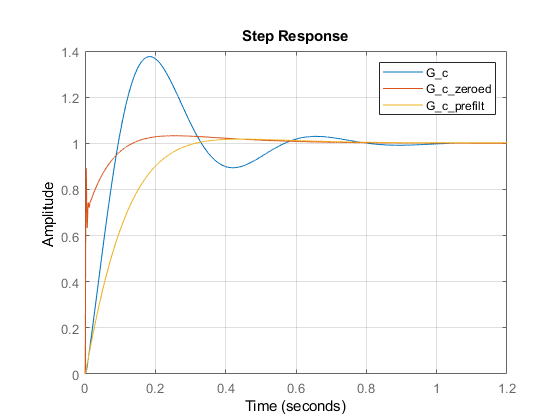

step(G_c, G_c_zeroed, G_c_prefilt)
legend
grid on


stepinfo(G_c_prefilt)

ans = struct with fields:
        RiseTime: 0.1865
    SettlingTime: 0.2743
     SettlingMin: 0.9001
     SettlingMax: 1.0180
       Overshoot: 1.7995
      Undershoot: 0
            Peak: 1.0180
        PeakTime: 0.4443



% Check size of u | u = F_y*F_r*S*r - F_y*G_d*S*d
F_y = minreal(F_y_zeroed)


F_y =
 
  250000 s^4 + 1.122e07 s^3 + 2.493e08 s^2 + 2.987e09 s + 9.947e09
  ----------------------------------------------------------------
                 s^4 + 3000 s^3 + 3e06 s^2 + 1e09 s
 
Continuous-time transfer function.



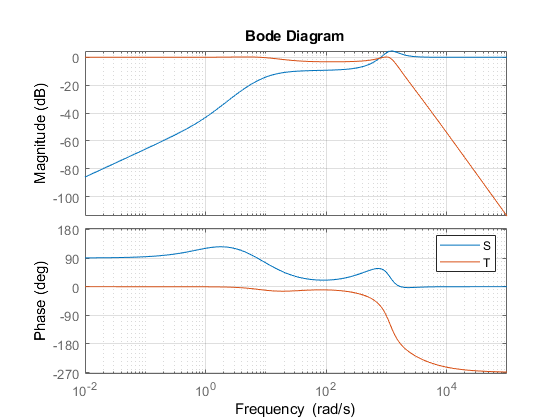

% Check sensitivity and complimentary sensitivity
S = 1/(1 + G*F_y);
T = G*F_y/(1 + G*F_y);
bode(S,T)
legend
grid on

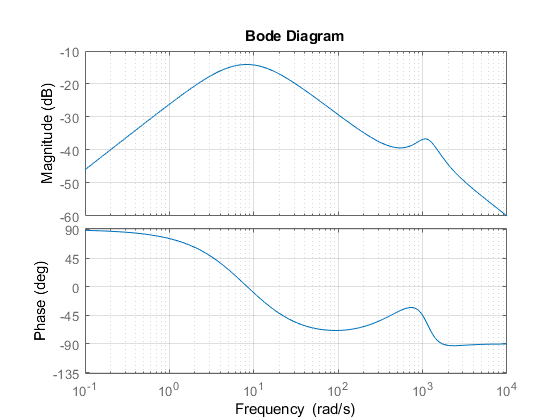


bode(G_d*S)
grid on

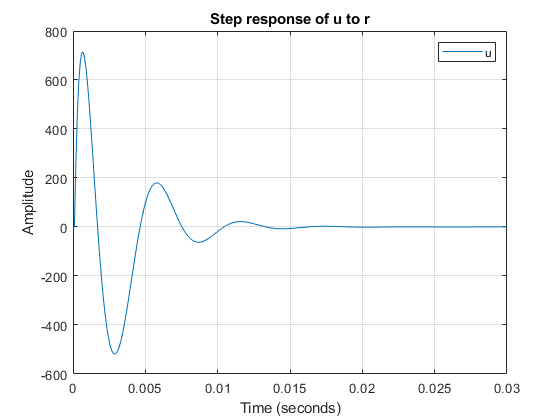


% Build r and d steps
t = linspace(0,.03,301);
r = ones(1,length(t));
d = ones(1,length(t));
r(1) = 0;
d(1:21) = 0;

[ref,~,~] = lsim(F_y*F_r*S,r,t);
[dist,~,~] = lsim(F_y*G_d*S,d,t);
u = ref - dist;

% Plot reference step
plot(t,ref)
title('Step response of u to r')
xlabel('Time (seconds)')
ylabel('Amplitude')
legend ('u')
grid on

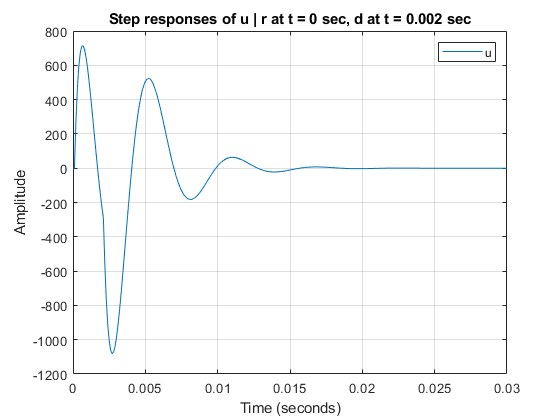


% Plot combo of reference step and disturbance
plot(t,u)
title('Step responses of u | r at t = 0 sec, d at t = 0.002 sec')
xlabel('Time (seconds)')
ylabel('Amplitude')
legend ('u')
grid on


%%%% Saves prior plot as pdf filling up page %%%%
set(1, 'PaperPosition', [0 0 5 5]); %Position plot at left hand corner with width 5 and height 5.
set(1, 'PaperSize', [5 5]); %Set the paper to have width 5 and height 5.
saveas(1, 'test', 'pdf')

%%%% Saves prior plot as pdf filling up page %%%%

## Functions

function new_sys = add_poles(sys, poles)
% Function to add poles to a transfer function
% poles is a vector containing all poles to add
    s = tf('s');
    
    for i = 1:length(poles)
        sys = sys * 1/((s/-poles(i))+1);
    end
    new_sys = sys;
end

function new_sys = add_zeros(sys, zeros)
% Function to add poles to a transfer function
% poles is a vector containing all poles to add
    s = tf('s');
    
    for i = 1:length(zeros)
        sys = sys * ((s/-zeros(i))+1);
    end
    new_sys = sys;
end